# **Deriving the cone fundamentals: a subspace intersection method - Figure 4**

We apply the subspace method to the WD Wright dichromat data.  As we note the in paper, the dichromats were not tested genetically to be sure they are reduction dichromats.  And there is another issue with one of the data sets, so we use the corrected form.  The calculation does illustrate the method.

## Load the corrected WD Wright data

thisW = 410:650;
load('cmfDeutanC.mat','wave','cmfDeutanC');
cmfDeutan = interp1(wave,cmfDeutanC,thisW');

load('cmfProtan.mat','wave','cmfProtan');
cmfProtan = interp1(wave,cmfProtan,thisW);

load('cmfTritan.mat','obsAverage');
cmfTritan = interp1(obsAverage.wave,obsAverage.CMF,thisW);

% These are the modern cone fundamentals.  We compare with them.
stockman = ieReadSpectra('stockmanEnergy.mat',thisW);

## L cone

The dashed lines are the estimates from the intersection method. The gray 'o's are the CIE cone fundamentals.

Form the N x 4 matrix, from the two dichromats.  Get the last vector from the SVD of this combined matrix.  The intersection from the deutan and tritan will be the L cone.

x = getlastVfromSVD([cmfDeutan -cmfTritan]);

We use the solution based on the CMFs from the deutan because it is the better of the two fits.  If we did not know the answer, we would be uncertain which one to choose.

Lest = ieScale(abs(cmfDeutan*x(1:2)),1);

## M cone

We use the solution based on the protan CMFs

x = getlastVfromSVD([cmfProtan -cmfTritan]);
Mest = ieScale(abs(cmfProtan*x(1:2)),1);

## S cone

Solution from the protan CMFs

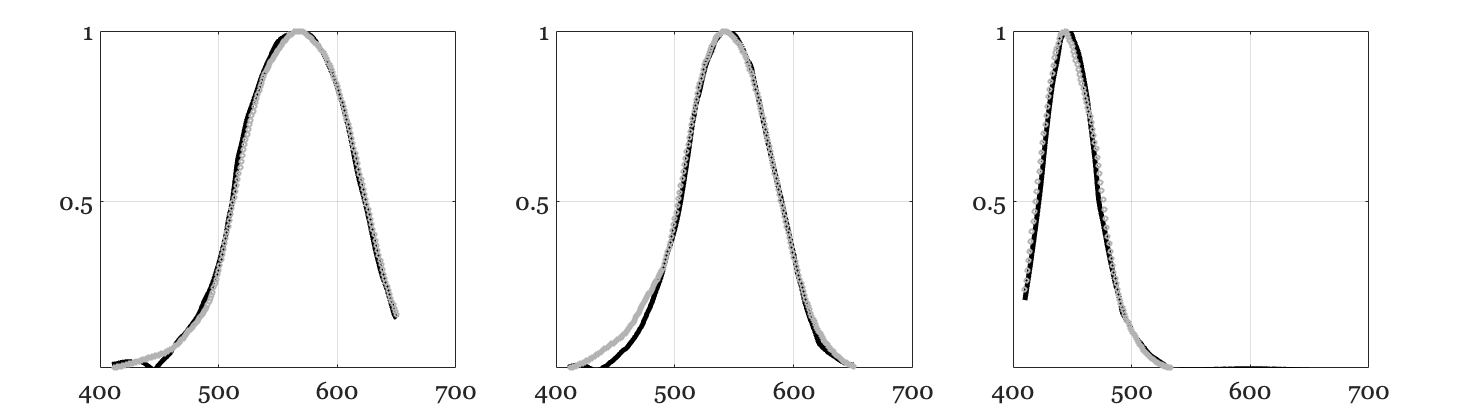

x = getlastVfromSVD([cmfProtan -cmfDeutan]);
Sest = ieScale(abs(cmfProtan*x(1:2)),1);

ieNewGraphWin([],'wide');
nexttile;
pL = plot(thisW,Lest,'k-',thisW,stockman(:,1),'ko','LineWidth',2);
grid on; set(gca,'ylim',[1e-2 1],'xlim',[400 700])
set(gca,'xtick',400:100:700,'ytick',0:0.5:1);
pL(1).LineWidth = 5; pL(1).Color = [0 0 0];
pL(2).Color = [0.7 0.7 0.7];pL(2).MarkerSize = 4;

nexttile;
pM = plot(thisW,Mest,'k-',thisW,stockman(:,2),'ko','LineWidth',2);
grid on; set(gca,'ylim',[1e-2 1],'xlim',[400 700])
set(gca,'xtick',400:100:700,'ytick',0:0.5:1);
pM(1).LineWidth = 5; pM(1).Color = [0 0 0];
pM(2).Color = [0.7 0.7 0.7]; pM(2).MarkerSize = 4;

nexttile;
pS = plot(thisW,Sest,'k-',thisW,stockman(:,3),'ko','LineWidth',2);
grid on; set(gca,'ylim',[1e-2 1],'xlim',[400 700])
set(gca,'xtick',400:100:700,'ytick',0:0.5:1);
pS(1).LineWidth = 5; pS(1).Color = [0 0 0];
pS(2).Color = [0.7 0.7 0.7];pS(2).MarkerSize = 4;
fontsize(gcf,24,'points');

## Make the log10 difference plots

Only show the difference if the cone sensitivity is 1/20th of the fundamental peak. Only consider positive sensitivities.

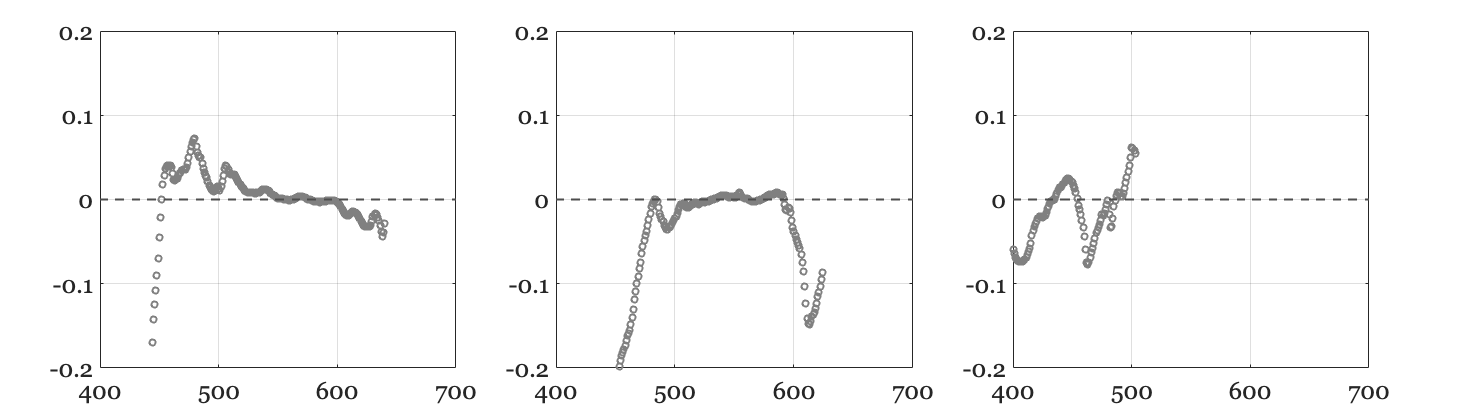

crit = log10(1/20);   % Stockman ration from peak (1)

ieNewGraphWin([],'wide');
tiledlayout(1,3);
nexttile
Lcone = max(Lest,0);  % No negative values
idx = log10(stockman(:,1)) > crit;  % Only plot down to 1 percent
p = plot(wave(idx),log10(Lcone(idx)) - log10(stockman(idx,1)),'ko','LineWidth',2);
grid on; set(gca,'ylim',[-0.2 0.2],'xlim',[400 700],'ytick',[-0.3:0.1:0.2],'xtick',[400:100:700]);
xaxisLine;
p.Color = [0.5 0.5 0.5];

nexttile
Mcone = max(Mest,0);
idx = log10(stockman(:,2)) > crit;
p = plot(wave(idx),log10(Mcone(idx)) - log10(stockman(idx,2)),'ko','LineWidth',2);
grid on; set(gca,'ylim',[-0.2 0.2],'xlim',[400 700],'ytick',[-0.3:0.1:0.2],'xtick',[400:100:700]);
xaxisLine;
p.Color = [0.5 0.5 0.5];

nexttile
Scone = max(Sest,0);
idx = log10(stockman(:,3)) > crit;
p = plot(wave(idx),log10(Scone(idx)) - log10(stockman(idx,3)),'ko','LineWidth',2);
grid on; set(gca,'ylim',[-0.2 0.2],'xlim',[400 700],'ytick',[-0.3:0.1:0.2],'xtick',[400:100:700]);
xaxisLine;
p.Color = [0.5 0.5 0.5];

fontsize(gcf,24,'points');